obsubsetM = importfileM('obsubset.xlsx');

Remove the lines with y = 0, we don't use those for input into ML 

obsubsetM(obsubsetM(:,23)==0,:) = [];
obsubsetM(1:5,:)

ans =        2763.3           72           73          100          119          139          156          165          189          188          156       2763.5            8           63          101          208          210          185          189          174          162          145           -1
       2762.8           10          112           96          117          136          153          180          177          632          182         2763           61           78          101          213          212          186          237          190          162          142           -1
       2762.3           65          119          149          183          186          153          189          190          187          376       2762.5           99           76           69           92          132          193          214          191          239          158           -1
       2761.8            6           99          134          152          608          151   

Remove the Bid/Ask Price. We want to see the prediction power of Level 2 open order levels

obsubsetM(:,[1, 12]) = [];

Standardize data for zero mean and unit variance

predictors = obsubsetM(:,1:end-1);
mu = mean(predictors);
mu = repmat(mu, [size(predictors, 1) ,1]);
sig = std(predictors);
sig = repmat(sig, [size(predictors, 1), 1]);
predictors = (predictors - mu) ./ sig; 

obsubsetMNormal = [predictors, obsubsetM(:, end)];

predictors = obsubsetM(:,1:end-1);
obsubs = [sum(predictors(:,1:end/2), 2), sum(predictors(:,end/2+1:end), 2), obsubsetM(:, end)];

Please, start the Classification Learner App and run it with below inputs

obookPred = obsubs(:,1:2)';
y = obsubs(:, end)';

diffObsubset = [zeros(1,size(obsubsetM(:,1:end-1),2)); diff(obsubsetM(:,1:end-1))];
diffObsubset(:,end+1) = obsubsetM(:, end);

LSTM - we will use predictors matrix and y response to train an LSTM network    

numFeatures = 20;
numResponses = 1;
numHiddenUnits = 100;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

lstmPreds = predictors'

lstmPreds =     72    10    65     6   111    56     7    58    59    86    56    89    57    52     3    65     1    63    76    78    67    15    51     9    40    50     5     3    50     1    84    49     1     9     3    48    44     1    53    55    12    54    24    10    62    48     4    43    12     2
    73   112   119    99   116   206   205   190   179    88    87    92    85    81    84    92    99    91    94    82    84    84    86    85    88    79    81    84    76    73    85    75    74    99   136   123    68    66    70    58    70    68    56    59    63    63    68    74    83   102
   100    96   149   134   580   413   424   427    96    90   106   101    97    88   108   111   113   124   128    82    95   116   118   116   111    81    97   148   130   132   140   135   135   145   133   123    75    89    74    63   108    87    92   101   115    80    90    90    99   126
   119   117   183   152   127   124   121   121   223   192   117   125   128   119 

y

y =     -1    -1    -1    -1     1    -1     1     1     1     1    -1     1     1    -1     1    -1     1     1     1     1    -1     1    -1     1     1    -1    -1     1    -1    -1     1    -1    -1    -1     1     1    -1     1     1    -1     1     1    -1    -1     1    -1     1    -1    -1     1


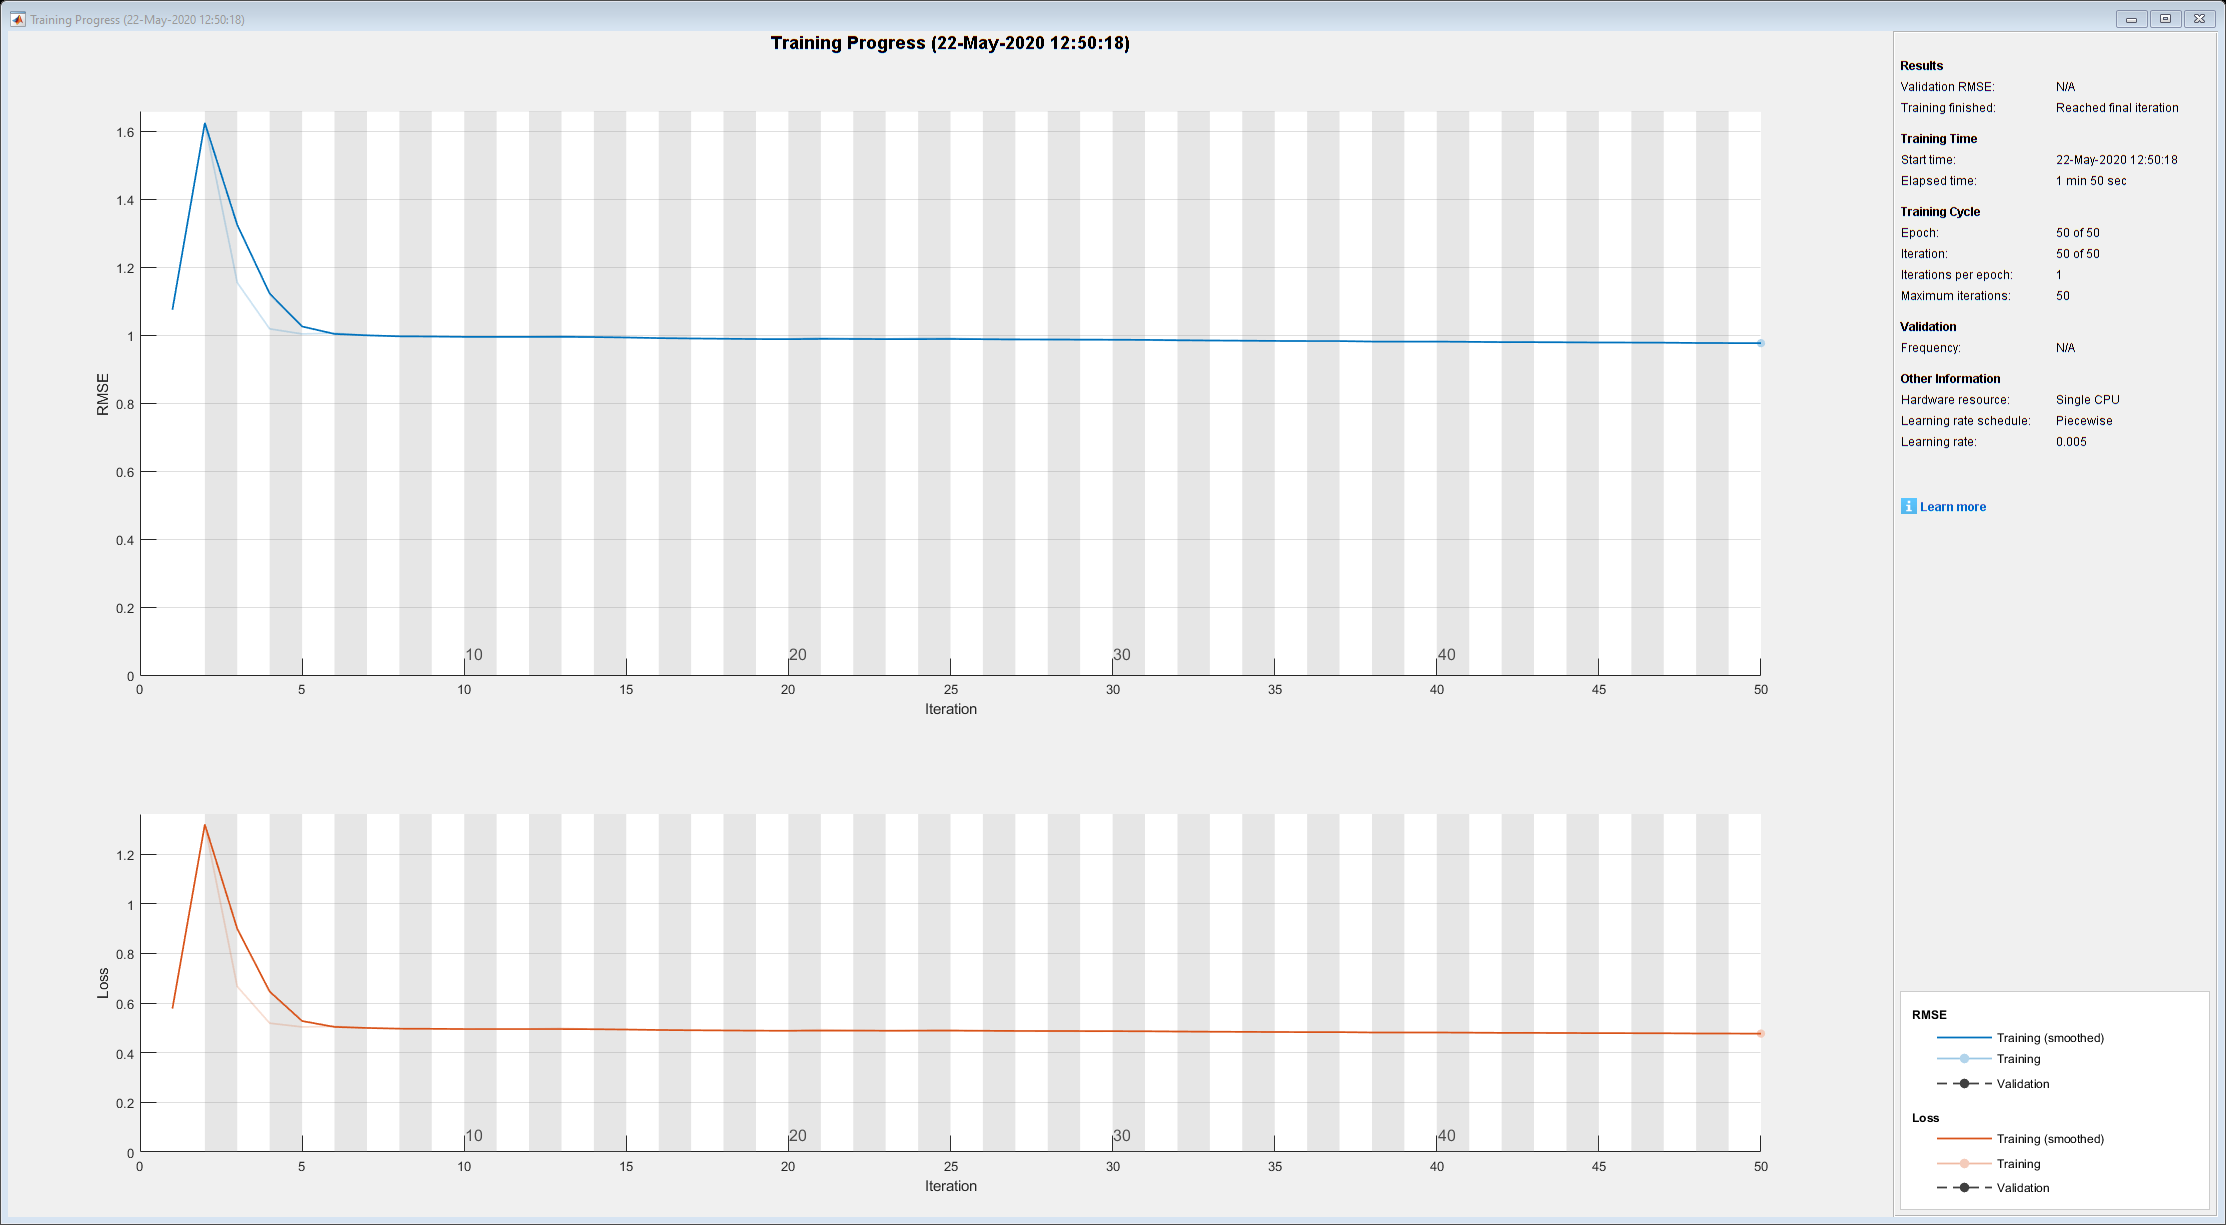

net = trainNetwork(lstmPreds,y,layers,options);